# **Strongly nonlinear snap-through example for adaptiveAnalyze**

Model:

  An asymmetric shallow two-bar truss with corotational geometry.

Comparison:

  1. Fine-step Newton analysis used as the numerical reference.

  2. Coarse-step ModifiedNewton analysis using adaptiveAnalyze.

  3. Independently stored reference values at selected displacements.

Expected adaptive behavior:

  - ModifiedNewton attempts fail near the limit points.

  - KrylovNewton and Newton are attempted.

  - Some failed displacement increments are subdivided.

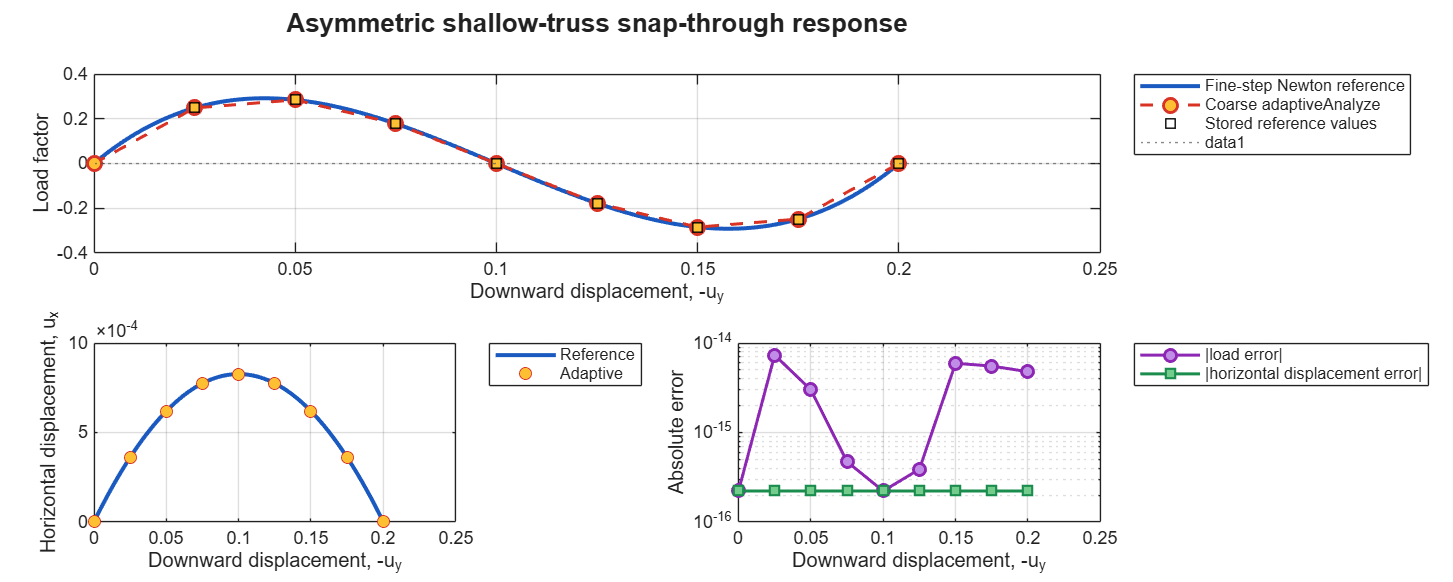

clear;
clc;
close all;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

### Analysis parameters

referenceIncrement = -5.0e-4;
referenceSteps = 400;

adaptiveIncrement = -2.5e-2;
adaptiveSteps = 8;

controlNode = 3;
controlDOF = 2;
loadPatternTag = 1;


### Fine-step reference analysis

buildShallowTrussModel(ops);

ops.constraints("Plain");
ops.numberer("Plain");
ops.system("BandGeneral");

ops.test("NormDispIncr", 1.0e-12, 50, 0);
ops.algorithm("Newton");
ops.integrator( ...
    "DisplacementControl", ...
    controlNode, controlDOF, referenceIncrement);
ops.analysis("Static");

reference = zeros(referenceSteps + 1, 4);
% Columns:
%   1: horizontal displacement of node 3
%   2: vertical displacement of node 3
%   3: vertical load magnitude
%   4: OpenSees load factor

reference(1, :) = [
    ops.nodeDisp(controlNode, 1), ...
    ops.nodeDisp(controlNode, 2), ...
    ops.getLoadFactor(loadPatternTag), ...
    ops.getLoadFactor(loadPatternTag)];

for step = 1:referenceSteps
    ok = ops.analyze(1);

    if ok ~= 0
        error( ...
            "Reference analysis failed at step %d with code %d.", ...
            step, ok);
    end

    loadFactor = ops.getLoadFactor(loadPatternTag);

    reference(step + 1, :) = [
        ops.nodeDisp(controlNode, 1), ...
        ops.nodeDisp(controlNode, 2), ...
        loadFactor, ...
        loadFactor];
end


### Coarse-step adaptive analysis

buildShallowTrussModel(ops);

ops.constraints("Plain");
ops.numberer("Plain");
ops.system("BandGeneral");

% Intentionally restrictive settings make the original ModifiedNewton
% configuration fail near strongly nonlinear portions of the path.
ops.test("NormDispIncr", 1.0e-12, 2, 0);
ops.algorithm("ModifiedNewton");
ops.integrator( ...
    "DisplacementControl", ...
    controlNode, controlDOF, adaptiveIncrement);
ops.analysis("Static");

adaptive = zeros(adaptiveSteps + 1, 4);
% Columns:
%   1: horizontal displacement of node 3
%   2: vertical displacement of node 3
%   3: vertical load magnitude
%   4: adaptiveAnalyze return code

adaptive(1, :) = [
    ops.nodeDisp(controlNode, 1), ...
    ops.nodeDisp(controlNode, 2), ...
    ops.getLoadFactor(loadPatternTag), ...
    0];

fprintf("\n");
fprintf("============================================================\n");

fprintf(" Adaptive coarse-step analysis\n");

 Adaptive coarse-step analysis


fprintf(" Watch for adaptiveAnalyze:: algorithm and subdivision output\n");

 Watch for adaptiveAnalyze:: algorithm and subdivision output


fprintf("============================================================\n\n");


for step = 1:adaptiveSteps
    fprintf( ...
        "\n--- Requested outer displacement step %d of %d ---\n", ...
        step, adaptiveSteps);

    ok = ops.adaptiveAnalyze(1, ...
        "-algorithms", "KrylovNewton", "Newton", ...
        "-subdivision", 0.5, 1.0e-6, 10, ...
        "-limits", 1000, ...
        "-debug");

    if ok ~= 0
        error( ...
            "Adaptive analysis failed at outer step %d with code %d.", ...
            step, ok);
    end

    adaptive(step + 1, :) = [
        ops.nodeDisp(controlNode, 1), ...
        ops.nodeDisp(controlNode, 2), ...
        ops.getLoadFactor(loadPatternTag), ...
        ok];
end


--- Requested outer displacement step 1 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 6.06609e-12 (max: 1e-12, Norm deltaR: 2.86138e-13)
[OpenSees] ModifiedNewton::solveCurrentStep() -the ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor 0.248201
[OpenSees] adaptiveAnalyze:: attemptResult code=-3 physicalTimeSeconds=0.0013565 iterations=3 norm=6.06609e-12
[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=2 algorithm=KrylovNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 6.06607e-12 (max: 1e-12, Norm deltaR: 8.38891e-13)
[OpenSees] AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::anal


--- Requested outer displacement step 2 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 2.76225e-12 (max: 1e-12, Norm deltaR: 5.8443e-14)
[OpenSees] ModifiedNewton::solveCurrentStep() -the ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor 0.284193
[OpenSees] adaptiveAnalyze:: attemptResult code=-3 physicalTimeSeconds=0.0022607 iterations=3 norm=2.76225e-12
[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=2 algorithm=KrylovNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 2.76224e-12 (max: 1e-12, Norm deltaR: 4.81453e-13)
[OpenSees] AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::analy


--- Requested outer displacement step 3 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] adaptiveAnalyze:: attemptResult code=0 physicalTimeSeconds=7.76e-05 iterations=2 norm=7.01655e-13
[OpenSees] adaptiveAnalyze:: success code=0 completedOuterSteps=1 requestedSteps=1 physicalTimeSeconds=0.0027796 attempts=1 acceptedSubsteps=1 subdivisions=0 lastIterations=2 lastNorm=7.01655e-13 lastStep=-0.025 lastAlgorithm=ModifiedNewton lastTest=NormDispIncr lastAnalyzeCode=0



--- Requested outer displacement step 4 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] adaptiveAnalyze:: attemptResult code=0 physicalTimeSeconds=8.17e-05 iterations=2 norm=6.66562e-17
[OpenSees] adaptiveAnalyze:: success code=0 completedOuterSteps=1 requestedSteps=1 physicalTimeSeconds=0.0025576 attempts=1 acceptedSubsteps=1 subdivisions=0 lastIterations=2 lastNorm=6.66562e-17 lastStep=-0.025 lastAlgorithm=ModifiedNewton lastTest=NormDispIncr lastAnalyzeCode=0



--- Requested outer displacement step 5 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] adaptiveAnalyze:: attemptResult code=0 physicalTimeSeconds=9.5e-05 iterations=2 norm=7.07309e-13
[OpenSees] adaptiveAnalyze:: success code=0 completedOuterSteps=1 requestedSteps=1 physicalTimeSeconds=0.0028375 attempts=1 acceptedSubsteps=1 subdivisions=0 lastIterations=2 lastNorm=7.07309e-13 lastStep=-0.025 lastAlgorithm=ModifiedNewton lastTest=NormDispIncr lastAnalyzeCode=0



--- Requested outer displacement step 6 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 2.80802e-12 (max: 1e-12, Norm deltaR: 5.1569e-14)
[OpenSees] ModifiedNewton::solveCurrentStep() -the ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor -0.284193
[OpenSees] adaptiveAnalyze:: attemptResult code=-3 physicalTimeSeconds=0.0023048 iterations=3 norm=2.80802e-12
[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=2 algorithm=KrylovNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 2.80801e-12 (max: 1e-12, Norm deltaR: 9.36209e-13)
[OpenSees] AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::anal


--- Requested outer displacement step 7 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 6.219e-12 (max: 1e-12, Norm deltaR: 1.00118e-13)
[OpenSees] ModifiedNewton::solveCurrentStep() -the ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor -0.248201
[OpenSees] adaptiveAnalyze:: attemptResult code=-3 physicalTimeSeconds=0.0021369 iterations=3 norm=6.219e-12
[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=2 algorithm=KrylovNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 6.21898e-12 (max: 1e-12, Norm deltaR: 1.23505e-12)
[OpenSees] AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::analyze


--- Requested outer displacement step 8 of 8 ---


[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=0 algorithm=ModifiedNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 1.07944e-11 (max: 1e-12, Norm deltaR: 6.21292e-13)
[OpenSees] ModifiedNewton::solveCurrentStep() -the ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor 1.93849e-13
[OpenSees] adaptiveAnalyze:: attemptResult code=-3 physicalTimeSeconds=0.0013126 iterations=3 norm=1.07944e-11
[OpenSees] adaptiveAnalyze:: attempt target=1 substep=1 stage=2 algorithm=KrylovNewton test=NormDispIncr step=-0.025
[OpenSees] WARNING: CTestNormDispIncr::test() - failed to converge 
[OpenSees] after: 2 iterations  current Norm: 1.07944e-11 (max: 1e-12, Norm deltaR: 1.66805e-12)
[OpenSees] AcceleratedNewton::solveCurrentStep() -The ConvergenceTest object failed in test()
[OpenSees] StaticAnalysis::a

### Independently stored reference values

% These values were obtained from the fine-step Newton solution using:
%
%   displacement increment = -5.0e-4
%   test tolerance         = 1.0e-12
%   maximum iterations     = 50
%
% Columns:
%   [horizontal displacement, vertical displacement, load factor]

publishedReference = [
     3.60712752838123e-4, -0.025,  2.48201205553051e-1
     6.19158366863243e-4, -0.050,  2.84192774311654e-1
     7.74542441814802e-4, -0.075,  1.77821500993599e-1
     8.26389841308204e-4, -0.100, -6.10622663543834e-16
     7.74542441814889e-4, -0.125, -1.77821500993605e-1
     6.19158366863171e-4, -0.150, -2.84192774311655e-1
     3.60712752838085e-4, -0.175, -2.48201205553024e-1
    -5.96848531392942e-17, -0.200,  0.0
];


### Compare the computed reference with the stored values

referenceAtCheckPoints = zeros(adaptiveSteps, 3);

for i = 1:adaptiveSteps
    targetDisplacement = publishedReference(i, 2);

    [~, index] = min(abs(reference(:, 2) - targetDisplacement));

    referenceAtCheckPoints(i, :) = [
        reference(index, 1), ...
        reference(index, 2), ...
        reference(index, 3)];
end

publishedHorizontalError = ...
    referenceAtCheckPoints(:, 1) - publishedReference(:, 1);

publishedLoadError = ...
    referenceAtCheckPoints(:, 3) - publishedReference(:, 3);

maxPublishedHorizontalError = max(abs(publishedHorizontalError));
maxPublishedLoadError = max(abs(publishedLoadError));


### Compare adaptive results with the fine-step reference

adaptiveReferenceLoad = interp1( ...
    -reference(:, 2), ...
    reference(:, 3), ...
    -adaptive(:, 2), ...
    "linear");

adaptiveLoadError = adaptive(:, 3) - adaptiveReferenceLoad;

adaptiveReferenceHorizontalDisp = interp1( ...
    -reference(:, 2), ...
    reference(:, 1), ...
    -adaptive(:, 2), ...
    "linear");

adaptiveHorizontalError = ...
    adaptive(:, 1) - adaptiveReferenceHorizontalDisp;

maxAdaptiveLoadError = max(abs(adaptiveLoadError));
maxAdaptiveHorizontalError = max(abs(adaptiveHorizontalError));


### Print comparison table


comparisonTable = table( ...
    (0:adaptiveSteps)', ...
    adaptive(:, 2), ...
    adaptive(:, 1), ...
    adaptive(:, 3), ...
    adaptiveReferenceLoad, ...
    adaptiveLoadError, ...
    adaptiveHorizontalError, ...
    'VariableNames', { ...
        'OuterStep', ...
        'VerticalDisplacement', ...
        'HorizontalDisplacement', ...
        'AdaptiveLoad', ...
        'ReferenceLoad', ...
        'LoadError', ...
        'HorizontalDisplacementError'});

fprintf("\n");
fprintf("============================================================\n");

fprintf(" Adaptive versus fine-step reference\n");

 Adaptive versus fine-step reference


fprintf("============================================================\n\n");

comparisonTable

comparisonTable = 9×7 table
    OuterStep    VerticalDisplacement    HorizontalDisplacement    AdaptiveLoad    ReferenceLoad     LoadError     HorizontalDisplacementError
    _________    ____________________    ______________________    ____________    _____________    ___________    ___________________________

        0                    0                          0                    0                0               0                      0        
        1               -0.025                 0.00036071               0.2482           0.2482     -7.3275e-15             6.5594e-17        
        2                -0.05                 0.00061916              0.28419          0.28419     -2.9976e-15             3.2092e-17        
        3         


fprintf("Maximum adaptive load error:              %.6e\n", ...
    maxAdaptiveLoadError);

Maximum adaptive load error:              7.327472e-15


fprintf("Maximum adaptive horizontal error:        %.6e\n", ...
    maxAdaptiveHorizontalError);

Maximum adaptive horizontal error:        2.017700e-16


fprintf("Maximum stored-reference load error:      %.6e\n", ...
    maxPublishedLoadError);

Maximum stored-reference load error:      3.053113e-16


fprintf("Maximum stored-reference horizontal error: %.6e\n", ...
    maxPublishedHorizontalError);

Maximum stored-reference horizontal error: 4.336809e-19


### Numerical checks

assert(all(adaptive(:, 4) == 0), ...
    "At least one adaptive outer step did not complete.");

assert(abs(adaptive(end, 2) + 0.2) < 1.0e-10, ...
    "The adaptive analysis did not reach the target displacement.");

assert(maxPublishedLoadError < 1.0e-8, ...
    "The fine-step solution does not match the stored load references.");

assert(maxPublishedHorizontalError < 1.0e-8, ...
    "The fine-step solution does not match the stored displacement references.");

assert(maxAdaptiveLoadError < 1.0e-7, ...
    "The adaptive load response differs excessively from the reference.");

assert(maxAdaptiveHorizontalError < 1.0e-7, ...
    "The adaptive horizontal response differs excessively from the reference.");


### Plot comparison

downwardReferenceDisp = -reference(:, 2);
downwardAdaptiveDisp = -adaptive(:, 2);

figure( ...
    "Color", "white", ...
    "Name", "adaptiveAnalyze strong nonlinear demonstration", ...
    "Position",[100 100 1500 600]);

layout = tiledlayout(2, 2, ...
    "TileSpacing", "compact", ...
    "Padding", "compact");

title(layout, ...
    "Asymmetric shallow-truss snap-through response", ...
    "FontWeight", "bold");

% Load-displacement response
nexttile([1, 2]);

plot( ...
    downwardReferenceDisp, reference(:, 3), ...
    "-", ...
    "Color", [0.10, 0.35, 0.75], ...
    "LineWidth", 2.0, ...
    "DisplayName", "Fine-step Newton reference");

hold on;

plot( ...
    downwardAdaptiveDisp, adaptive(:, 3), ...
    "o--", ...
    "Color", [0.85, 0.20, 0.15], ...
    "MarkerFaceColor", [1.00, 0.75, 0.20], ...
    "MarkerSize", 7, ...
    "LineWidth", 1.5, ...
    "DisplayName", "Coarse adaptiveAnalyze");

plot( ...
    -publishedReference(:, 2), publishedReference(:, 3), ...
    "ks", ...
    "MarkerSize", 6, ...
    "LineWidth", 1.0, ...
    "DisplayName", "Stored reference values");

yline(0.0, ":", "Color", [0.35, 0.35, 0.35]);
grid on;
box on;

xlabel("Downward displacement, -u_y");
ylabel("Load factor");
legend("Location", "bestoutside");

% Horizontal equilibrium response
nexttile;

plot( ...
    downwardReferenceDisp, reference(:, 1), ...
    "-", ...
    "Color", [0.10, 0.35, 0.75], ...
    "LineWidth", 2.0, ...
    "DisplayName", "Reference");

hold on;

plot( ...
    downwardAdaptiveDisp, adaptive(:, 1), ...
    "o", ...
    "Color", [0.85, 0.20, 0.15], ...
    "MarkerFaceColor", [1.00, 0.75, 0.20], ...
    "MarkerSize", 6, ...
    "DisplayName", "Adaptive");

grid on;
box on;

xlabel("Downward displacement, -u_y");
ylabel("Horizontal displacement, u_x");
legend("Location", "bestoutside");

% Adaptive error
nexttile;

semilogy( ...
    downwardAdaptiveDisp, ...
    max(abs(adaptiveLoadError), eps), ...
    "o-", ...
    "Color", [0.55, 0.15, 0.70], ...
    "MarkerFaceColor", [0.75, 0.55, 0.90], ...
    "LineWidth", 1.5, ...
    "DisplayName", "|load error|");

hold on;

semilogy( ...
    downwardAdaptiveDisp, ...
    max(abs(adaptiveHorizontalError), eps), ...
    "s-", ...
    "Color", [0.10, 0.55, 0.30], ...
    "MarkerFaceColor", [0.45, 0.80, 0.55], ...
    "LineWidth", 1.5, ...
    "DisplayName", "|horizontal displacement error|");

grid on;
box on;

xlabel("Downward displacement, -u_y");
ylabel("Absolute error");
legend("Location", "bestoutside");


fprintf("\nAll reference and adaptive comparison checks passed.\n");


All reference and adaptive comparison checks passed.


ops.wipe();

### Local function

function buildShallowTrussModel(ops)
%BUILDSHALLOWTRUSSMODEL Create an asymmetric two-bar snap-through model.

ops.wipe();

ops.model("basic", "-ndm", 2, "-ndf", 2);

% Support nodes and shallow apex.
ops.node(1, -1.0, 0.0);
ops.node(2,  1.2, 0.0);
ops.node(3,  0.0, 0.1);

ops.fix(1, 1, 1);
ops.fix(2, 1, 1);
ops.fix(3, 0, 0);

% The material is elastic. Strong nonlinearity is produced by the
% corotational geometry and shallow snap-through configuration.
ops.uniaxialMaterial("Elastic", 1, 1000.0);

ops.element("corotTruss", 1, 1, 3, 1.0, 1);
ops.element("corotTruss", 2, 2, 3, 1.0, 1);

ops.timeSeries("Linear", 1);
ops.pattern("Plain", 1, 1);

% Unit downward reference load. Therefore, the load factor is also the
% magnitude of the applied vertical load.
ops.load(3, 0.0, -1.0);
end